% data = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv', 'ReadVariableNames',1);
% dates = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv');
% Confounding = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Confounding/Confounding_Dataset.csv', 'ReadVariableNames',1);

data = readtable('Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv', 'ReadVariableNames',1);
dates = readtable('Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv');
Confounding = readtable('Datasets/Confounding/Confounding_Dataset.csv', 'ReadVariableNames',1);
AQI_data = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/AQI_Features.csv')

AQI_data = 832×8 table
         State                  County                          CS                   MaxAQI    x90thPercentileAQI    MedianAQI    AQI_Class_KM    Extreme_AQI
    ________________    ______________________    _______________________________    ______    __________________    _________    ____________    ___________

    'Alabama'           'Baldwin'                 'BaldwinAlabama'                    129      52.667                 36.833      1               0          
    'Alabama'           'Colbert'                 'ColbertAlabama'                    115      49.667                 36.667      1               0          
    'Alabama'           'DeKalb'                  'DeKalbAlabama'       

AQI_Classes = AQI_data.AQI_Class_KM; 

NC = zeros(832,3)

NC =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


NC(AQI_Classes==1,2) = 1;
NC(AQI_Classes==2,3) = 1;
NC(AQI_Classes==3,1) = 1;

Total_Population = (Confounding.TOT_POP);
cases = table2array(data(:,12:173));
cases = cases./Total_Population;

US = 256;
[rC, cC] = size(cases);
splines = zeros(rC,US);

for t = 1:rC
    casesS = cases(t,:);
    casesS = nonzeros(casesS); % non-zero cases 
    if length(casesS)>1
        x = [1:length(casesS)]';  % number of days since first case 
        f = fit(x, casesS, 'cubicinterp');
        xeval = linspace(1, length(casesS), US);
        sp_eval = f(xeval)';
        splines(t,:)= sp_eval;
    end 
end 

diff_splines =    1.0e-03 *

   -0.0269   -0.0289   -0.0309   -0.0330   -0.0352   -0.0377   -0.0406   -0.0441   -0.0482   -0.0522   -0.0551   -0.0573   -0.0602   -0.0643   -0.0691   -0.0742   -0.0796   -0.0850   -0.0901   -0.0946   -0.0991   -0.1045   -0.1118   -0.1200   -0.1270   -0.1330   -0.1411   -0.1527   -0.1639   -0.1700   -0.1718   -0.1734   -0.1772   -0.1832   -0.1914   -0.2020   -0.2151   -0.2305   -0.2482   -0.2666   -0.2824   -0.2940   -0.3045   -0.3177   -0.3337   -0.3500   -0.3668   -0.3872   -0.4131   -0.4385
   -0.0133   -0.0156   -0.0175   -0.0192   -0.0213   -0.0240   -0.0277   -0.0314   -0.0337   -0.0334   -0.0292   -0.0201   -0.0089   -0.0015   -0.0020   -0.0083   -0.0169   -0.0248   -0.0300   -0.0309   -0.0298   -0.0310   -0.0369   -0.0460   -0.0564   -0.0661   -0.0731   -0.0766   -0.0798   -0.0874   -0.1001   -0.1134   -0.1225   -0.1289   -0.1376   -0.1517   -0.1697   -0.1895   -0.2092   -0.2263   -0.2379   -0.2474   -0.2619   -0.2845   -0.3091   -0.3280   -0.3408

sn = 508

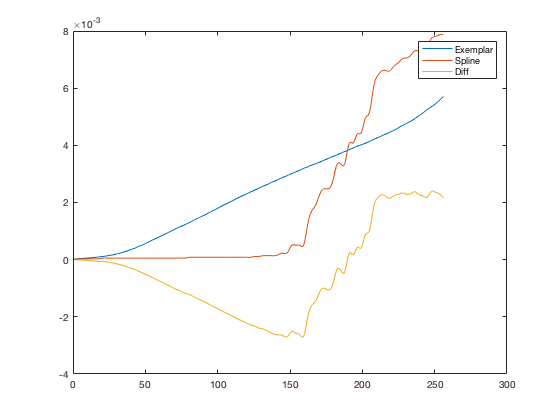

exemplar = mean(splines);
diff_splines = zeros(rC,US);

for t = 1:rC
    diff_splines(t,:) = splines(t,:)-exemplar;
end